# Formula derivation

## Creating symbolic variables

syms m R L J K mu_r mu_lx mu_ly r_m r_b positive
syms theta_l(t) theta_r(t) i_l(t) i_r(t) u_l(t) u_r(t)
dtl = diff(theta_l, t);
dtr = diff(theta_r, t);
ddtl = diff(dtl, t);
ddtr = diff(dtr, t);
dddtl = diff(ddtl, t);
dddtr = diff(ddtr, t);
il = i_l;
ir = i_r;
dil = diff(il, t);
dir = diff(ir, t);

syms dx dy tel ter real

## Defining formulas

mddx = (tel + ter)/r_m - 4*mu_r*(dtl+dtr)*r_m/r_b - 2*mu_lx*dx;
mddy = (tel - ter)/r_m - 2*mu_r*(dtl-dtr)*r_m/r_b - 2*mu_ly*dy;

mddx = subs(mddx, dx, (dtl+dtr)*r_m/2);  % m * x_dot_dot = mddx
mddy = subs(mddy, dy, (dtl-dtr)*r_m/2);  % m * y_dot_dot = mddy

% mddtl = m * d^2/dt^2(theta_l) = (mddx + mddy) / r_m
% uitgedrukt in: tau_ext,l; tau_ext,r; d/dt(tau_l); d/dt(tau_r)
mddtl = collect(expand((mddx + mddy) / r_m), [tel, ter, dtl, dtr]);
% tau_ext,l = J * d^2/dt^2(theta_l) + K * i_l
mddtl = subs(mddtl, tel, K*il - J*ddtl);

% hetzelfde voor mddtr en tau_ext,r (ter)
mddtr = collect(expand((mddx - mddy) / r_m), [tel, ter, dtl, dtr]);
mddtr = subs(mddtr, ter, K*ir - J*ddtr);

% dit is de formule voor i_l = ... uitgedrukt in d^2/dt^2(theta_r), d/dt(theta_l), d/dt(theta_r)
formula_il = collect(solve(m*ddtl == mddtl, il), [ddtl, dtl, dtr])

$$formula\_il = \frac{{r_{m}}^{2}\,\left(m+\frac{2\,J}{{r_{m}}^{2}}\right)}{2\,K}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{l}\left(t\right)+\frac{{r_{m}}^{2}\,\left(\mu_{\mathrm{lx}}+\mu_{\mathrm{ly}}+\frac{6\,\mu_{r}}{r_{b}}\right)}{2\,K}\,\frac{\partial }{\partial t}\theta_{l}\left(t\right)+\frac{{r_{m}}^{2}\,\left(\mu_{\mathrm{lx}}-\mu_{\mathrm{ly}}+\frac{2\,\mu_{r}}{r_{b}}\right)}{2\,K}\,\frac{\partial }{\partial t}\theta_{r}\left(t\right)$$

% dit is de formule voor i_r = ... uitgedrukt in d^2/dt^2(theta_r), d/dt(theta_l), d/dt(theta_r)
formula_ir = collect(solve(m*ddtr == mddtr, ir), [ddtr, dtl, dtr])

$$formula\_ir = \frac{{r_{m}}^{2}\,\left(m+\frac{2\,J}{{r_{m}}^{2}}\right)}{2\,K}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{r}\left(t\right)+\frac{{r_{m}}^{2}\,\left(\mu_{\mathrm{lx}}-\mu_{\mathrm{ly}}+\frac{2\,\mu_{r}}{r_{b}}\right)}{2\,K}\,\frac{\partial }{\partial t}\theta_{l}\left(t\right)+\frac{{r_{m}}^{2}\,\left(\mu_{\mathrm{lx}}+\mu_{\mathrm{ly}}+\frac{6\,\mu_{r}}{r_{b}}\right)}{2\,K}\,\frac{\partial }{\partial t}\theta_{r}\left(t\right)$$

% dit is de formule voor u_l = ...
formula_ul = collect(L*diff(formula_il, t) + R*formula_il + K*dtl, [dddtl, ddtl, ddtr, dtl, dtr])

$$formula\_ul(t) = \begin{array}{l} \frac{L\,{r_{m}}^{2}\,\sigma_{1}}{2\,K}\,\frac{\partial^{3}}{\partial t^{3}}\theta_{l}\left(t\right)+\left(\frac{L\,{r_{m}}^{2}\,\sigma_{2}}{2\,K}+\frac{R\,{r_{m}}^{2}\,\sigma_{1}}{2\,K}\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{l}\left(t\right)+\frac{L\,{r_{m}}^{2}\,\sigma_{3}}{2\,K}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{r}\left(t\right)+\left(K+\frac{R\,{r_{m}}^{2}\,\sigma_{2}}{2\,K}\right)\,\frac{\partial }{\partial t}\theta_{l}\left(t\right)+\frac{R\,{r_{m}}^{2}\,\sigma_{3}}{2\,K}\,\frac{\partial }{\partial t}\theta_{r}\left(t\right)\\ \mathrm{where}\\ \sigma_{1}=m+\frac{2\,J}{{r_{m}}^{2}}\\ \sigma_{2}=\mu_{\mathrm{lx}}+\mu_{\mathrm{ly}}+\frac{6\,\mu_{r}}{r_{b}}\\ \sigma_{3}=\mu_{\mathrm{lx}}-\mu_{\mathrm{ly}}+\frac{2\,\mu_{r}}{r_{b}} \end{array}$$

% dit is de formule voor u_r = ...
formula_ur = collect(L*diff(formula_ir, t) + R*formula_ir + K*dtr, [dddtr, ddtl, ddtr, dtl, dtr])

$$formula\_ur(t) = \begin{array}{l} \frac{L\,{r_{m}}^{2}\,\sigma_{1}}{2\,K}\,\frac{\partial^{3}}{\partial t^{3}}\theta_{r}\left(t\right)+\frac{L\,{r_{m}}^{2}\,\sigma_{3}}{2\,K}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{l}\left(t\right)+\left(\frac{L\,{r_{m}}^{2}\,\sigma_{2}}{2\,K}+\frac{R\,{r_{m}}^{2}\,\sigma_{1}}{2\,K}\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{r}\left(t\right)+\frac{R\,{r_{m}}^{2}\,\sigma_{3}}{2\,K}\,\frac{\partial }{\partial t}\theta_{l}\left(t\right)+\left(K+\frac{R\,{r_{m}}^{2}\,\sigma_{2}}{2\,K}\right)\,\frac{\partial }{\partial t}\theta_{r}\left(t\right)\\ \mathrm{where}\\ \sigma_{1}=m+\frac{2\,J}{{r_{m}}^{2}}\\ \sigma_{2}=\mu_{\mathrm{lx}}+\mu_{\mathrm{ly}}+\frac{6\,\mu_{r}}{r_{b}}\\ \sigma_{3}=\mu_{\mathrm{lx}}-\mu_{\mathrm{ly}}+\frac{2\,\mu_{r}}{r_{b}} \end{array}$$

% dit is de formule voor d^3/dt^3(theta_l) = ...
formula_dddtl = collect(expand(solve(formula_ul == u_l, dddtl)), [dddtl, ddtl, ddtr, dtl, dtr])

$$formula\_dddtl = \begin{array}{l} \left(-\frac{J\,R\,2}{\sigma_{6}}-\frac{L\,\mu_{r}\,{r_{m}}^{2}\,6}{\sigma_{1}}-\sigma_{5}-\sigma_{4}-\frac{R\,m\,{r_{m}}^{2}}{\sigma_{6}}\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{l}\left(t\right)+\left(-\frac{L\,\mu_{r}\,{r_{m}}^{2}\,2}{\sigma_{1}}-\sigma_{5}+\sigma_{4}\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{r}\left(t\right)+\left(-\frac{K^{2}\,2}{\sigma_{6}}-\frac{R\,\mu_{r}\,{r_{m}}^{2}\,6}{\sigma_{1}}-\sigma_{3}-\sigma_{2}\right)\,\frac{\partial }{\partial t}\theta_{l}\left(t\right)+\left(-\frac{R\,\mu_{r}\,{r_{m}}^{2}\,2}{\sigma_{1}}-\sigma_{3}+\sigma_{2}\right)\,\frac{\partial }{\partial t}\theta_{r}\left(t\right)+\frac{K\,u_{l}\left(t\right)\,2}{\sigma_{6}}\\ \mathrm{where}\\ \sigma_{1}=L\,m\,r_{b}\,{r_{m}}^{2}+2\,J\,L\,r_{b}\\ \sigma_{2}=\frac{R\,\mu_{\mathrm{ly}}\,{r_{m}}^{2}}{\sigma_{6}}\\ \sigma_{3}=\frac{R\,\mu_{\mathrm{lx}}\,{r_{m}}^{2}}{\sigma_{6}}\\ \sigma_{4}=\frac{L\,\mu_{\mathrm{ly}}\,{r_{m}}^{2}}{\sigma_{6}}\\ \sigma_{5}=\frac{L\,\mu_{\mathrm{lx}}\,{r_{m}}^{2}}{\sigma_{6}}\\ \sigma_{6}=L\,m\,{r_{m}}^{2}+2\,J\,L \end{array}$$

% dit is de formule voor d^3/dt^3(theta_r) = ...
formula_dddtr = collect(expand(solve(formula_ur == u_r, dddtr)), [dddtr, ddtl, ddtr, dtl, dtr])

$$formula\_dddtr = \begin{array}{l} \left(-\frac{L\,\mu_{r}\,{r_{m}}^{2}\,2}{\sigma_{1}}-\sigma_{5}+\sigma_{4}\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{l}\left(t\right)+\left(-\frac{J\,R\,2}{\sigma_{6}}-\frac{L\,\mu_{r}\,{r_{m}}^{2}\,6}{\sigma_{1}}-\sigma_{5}-\sigma_{4}-\frac{R\,m\,{r_{m}}^{2}}{\sigma_{6}}\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{r}\left(t\right)+\left(-\frac{R\,\mu_{r}\,{r_{m}}^{2}\,2}{\sigma_{1}}-\sigma_{3}+\sigma_{2}\right)\,\frac{\partial }{\partial t}\theta_{l}\left(t\right)+\left(-\frac{K^{2}\,2}{\sigma_{6}}-\frac{R\,\mu_{r}\,{r_{m}}^{2}\,6}{\sigma_{1}}-\sigma_{3}-\sigma_{2}\right)\,\frac{\partial }{\partial t}\theta_{r}\left(t\right)+\frac{K\,u_{r}\left(t\right)\,2}{\sigma_{6}}\\ \mathrm{where}\\ \sigma_{1}=L\,m\,r_{b}\,{r_{m}}^{2}+2\,J\,L\,r_{b}\\ \sigma_{2}=\frac{R\,\mu_{\mathrm{ly}}\,{r_{m}}^{2}}{\sigma_{6}}\\ \sigma_{3}=\frac{R\,\mu_{\mathrm{lx}}\,{r_{m}}^{2}}{\sigma_{6}}\\ \sigma_{4}=\frac{L\,\mu_{\mathrm{ly}}\,{r_{m}}^{2}}{\sigma_{6}}\\ \sigma_{5}=\frac{L\,\mu_{\mathrm{lx}}\,{r_{m}}^{2}}{\sigma_{6}}\\ \sigma_{6}=L\,m\,{r_{m}}^{2}+2\,J\,L \end{array}$$

% dit zijn de coefficienten die daar horen bij:
% d/dt(theta_l), d/dt(theta_r), d^2/dt^2(theta_l), d^2/dt^2(theta_r), u_l, u_r
[Cl, Tl] = coeffs(formula_dddtl, [dtl, dtr, ddtl, ddtr, u_l, u_r])

$$Cl = \begin{array}{l} \left(\begin{array}{ccccc} -\frac{2\,K^{2}}{\sigma_{6}}-\frac{6\,R\,\mu_{r}\,{r_{m}}^{2}}{\sigma_{1}}-\sigma_{3}-\sigma_{2} & \sigma_{2}-\sigma_{3}-\frac{2\,R\,\mu_{r}\,{r_{m}}^{2}}{\sigma_{1}} & -\frac{2\,J\,R}{\sigma_{6}}-\frac{6\,L\,\mu_{r}\,{r_{m}}^{2}}{\sigma_{1}}-\sigma_{5}-\sigma_{4}-\frac{R\,m\,{r_{m}}^{2}}{\sigma_{6}} & \sigma_{4}-\sigma_{5}-\frac{2\,L\,\mu_{r}\,{r_{m}}^{2}}{\sigma_{1}} & \frac{K\,2}{\sigma_{6}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L\,m\,r_{b}\,{r_{m}}^{2}+2\,J\,L\,r_{b}\\ \sigma_{2}=\frac{R\,\mu_{\mathrm{ly}}\,{r_{m}}^{2}}{\sigma_{6}}\\ \sigma_{3}=\frac{R\,\mu_{\mathrm{lx}}\,{r_{m}}^{2}}{\sigma_{6}}\\ \sigma_{4}=\frac{L\,\mu_{\mathrm{ly}}\,{r_{m}}^{2}}{\sigma_{6}}\\ \sigma_{5}=\frac{L\,\mu_{\mathrm{lx}}\,{r_{m}}^{2}}{\sigma_{6}}\\ \sigma_{6}=L\,m\,{r_{m}}^{2}+2\,J\,L \end{array}$$

$$Tl = \left(\begin{array}{ccccc} \frac{\partial }{\partial t}\theta_{l}\left(t\right) & \frac{\partial }{\partial t}\theta_{r}\left(t\right) & \frac{\partial^{2}}{\partial t^{2}}\theta_{l}\left(t\right) & \frac{\partial^{2}}{\partial t^{2}}\theta_{r}\left(t\right) & u_{l}\left(t\right) \end{array}\right)$$

[Cr, Tr] = coeffs(formula_dddtr, [dtl, dtr, ddtl, ddtr, u_l, u_r])

$$Cr = \begin{array}{l} \left(\begin{array}{ccccc} \sigma_{2}-\sigma_{3}-\frac{2\,R\,\mu_{r}\,{r_{m}}^{2}}{\sigma_{1}} & -\frac{2\,K^{2}}{\sigma_{6}}-\frac{6\,R\,\mu_{r}\,{r_{m}}^{2}}{\sigma_{1}}-\sigma_{3}-\sigma_{2} & \sigma_{4}-\sigma_{5}-\frac{2\,L\,\mu_{r}\,{r_{m}}^{2}}{\sigma_{1}} & -\frac{2\,J\,R}{\sigma_{6}}-\frac{6\,L\,\mu_{r}\,{r_{m}}^{2}}{\sigma_{1}}-\sigma_{5}-\sigma_{4}-\frac{R\,m\,{r_{m}}^{2}}{\sigma_{6}} & \frac{K\,2}{\sigma_{6}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L\,m\,r_{b}\,{r_{m}}^{2}+2\,J\,L\,r_{b}\\ \sigma_{2}=\frac{R\,\mu_{\mathrm{ly}}\,{r_{m}}^{2}}{\sigma_{6}}\\ \sigma_{3}=\frac{R\,\mu_{\mathrm{lx}}\,{r_{m}}^{2}}{\sigma_{6}}\\ \sigma_{4}=\frac{L\,\mu_{\mathrm{ly}}\,{r_{m}}^{2}}{\sigma_{6}}\\ \sigma_{5}=\frac{L\,\mu_{\mathrm{lx}}\,{r_{m}}^{2}}{\sigma_{6}}\\ \sigma_{6}=L\,m\,{r_{m}}^{2}+2\,J\,L \end{array}$$

$$Tr = \left(\begin{array}{ccccc} \frac{\partial }{\partial t}\theta_{l}\left(t\right) & \frac{\partial }{\partial t}\theta_{r}\left(t\right) & \frac{\partial^{2}}{\partial t^{2}}\theta_{l}\left(t\right) & \frac{\partial^{2}}{\partial t^{2}}\theta_{r}\left(t\right) & u_{r}\left(t\right) \end{array}\right)$$

simplify(Cl(3))

$$ans = -\frac{2\,J\,R\,r_{b}+6\,L\,\mu_{r}\,{r_{m}}^{2}+L\,\mu_{\mathrm{lx}}\,r_{b}\,{r_{m}}^{2}+L\,\mu_{\mathrm{ly}}\,r_{b}\,{r_{m}}^{2}+R\,m\,r_{b}\,{r_{m}}^{2}}{L\,r_{b}\,\left(m\,{r_{m}}^{2}+2\,J\right)}$$

simplify(Cr(4))

$$ans = -\frac{2\,J\,R\,r_{b}+6\,L\,\mu_{r}\,{r_{m}}^{2}+L\,\mu_{\mathrm{lx}}\,r_{b}\,{r_{m}}^{2}+L\,\mu_{\mathrm{ly}}\,r_{b}\,{r_{m}}^{2}+R\,m\,r_{b}\,{r_{m}}^{2}}{L\,r_{b}\,\left(m\,{r_{m}}^{2}+2\,J\right)}$$

A = [zeros(4,2), eye(4);
    0, 0, simplify(Cl(1:4));
    0, 0, simplify(Cr(1:4))];
A

$$A = \begin{array}{l} \left(\begin{array}{cccccc} 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & \sigma_{3} & \sigma_{4} & \sigma_{2} & \sigma_{1}\\ 0 & 0 & \sigma_{4} & \sigma_{3} & \sigma_{1} & \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{{r_{m}}^{2}\,\left(2\,\mu_{r}+\mu_{\mathrm{lx}}\,r_{b}-\mu_{\mathrm{ly}}\,r_{b}\right)}{r_{b}\,\left(m\,{r_{m}}^{2}+2\,J\right)}\\ \sigma_{2}=-\frac{2\,J\,R\,r_{b}+6\,L\,\mu_{r}\,{r_{m}}^{2}+L\,\mu_{\mathrm{lx}}\,r_{b}\,{r_{m}}^{2}+L\,\mu_{\mathrm{ly}}\,r_{b}\,{r_{m}}^{2}+R\,m\,r_{b}\,{r_{m}}^{2}}{\sigma_{5}}\\ \sigma_{3}=-\frac{2\,K^{2}\,r_{b}+6\,R\,\mu_{r}\,{r_{m}}^{2}+R\,\mu_{\mathrm{lx}}\,r_{b}\,{r_{m}}^{2}+R\,\mu_{\mathrm{ly}}\,r_{b}\,{r_{m}}^{2}}{\sigma_{5}}\\ \sigma_{4}=-\frac{R\,{r_{m}}^{2}\,\left(2\,\mu_{r}+\mu_{\mathrm{lx}}\,r_{b}-\mu_{\mathrm{ly}}\,r_{b}\right)}{\sigma_{5}}\\ \sigma_{5}=L\,r_{b}\,\left(m\,{r_{m}}^{2}+2\,J\right) \end{array}$$

B = simplify([zeros(4, 2); Cl(5), 0; 0, Cr(5)])

$$B = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ \frac{2\,K}{L\,\left(m\,{r_{m}}^{2}+2\,J\right)} & 0\\ 0 & \frac{2\,K}{L\,\left(m\,{r_{m}}^{2}+2\,J\right)} \end{array}\right)$$


% What is A if mu_lx = mu_ly and r_b = r_m
As = simplify(subs(A, [mu_ly, r_b], [mu_lx, r_m]))

$$As = \begin{array}{l} \left(\begin{array}{cccccc} 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & \sigma_{3} & -\frac{2\,R\,\mu_{r}\,r_{m}}{\sigma_{4}} & \sigma_{2} & \sigma_{1}\\ 0 & 0 & -\frac{2\,R\,\mu_{r}\,r_{m}}{\sigma_{4}} & \sigma_{3} & \sigma_{1} & \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{2\,\mu_{r}\,r_{m}}{m\,{r_{m}}^{2}+2\,J}\\ \sigma_{2}=-\frac{2\,J\,R+6\,L\,\mu_{r}\,r_{m}+2\,L\,\mu_{\mathrm{lx}}\,{r_{m}}^{2}+R\,m\,{r_{m}}^{2}}{\sigma_{4}}\\ \sigma_{3}=-\frac{2\,K^{2}+2\,R\,\mu_{\mathrm{lx}}\,{r_{m}}^{2}+6\,R\,\mu_{r}\,r_{m}}{\sigma_{4}}\\ \sigma_{4}=L\,\left(m\,{r_{m}}^{2}+2\,J\right) \end{array}$$

% What is A if there also is no friction: mu_l = 0 and mu_r = 0
Avs = simplify(subs(As, [mu_lx, mu_r], [0, 0]))

$$Avs = \begin{array}{l} \left(\begin{array}{cccccc} 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & \sigma_{1} & 0 & -\frac{R}{L} & 0\\ 0 & 0 & 0 & \sigma_{1} & 0 & -\frac{R}{L} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{2\,K^{2}}{L\,\left(m\,{r_{m}}^{2}+2\,J\right)} \end{array}$$

T_small = r_m/2*[1, 1; 1, -1]

$$T\_small = \left(\begin{array}{cc} \frac{r_{m}}{2} & \frac{r_{m}}{2}\\ \frac{r_{m}}{2} & -\frac{r_{m}}{2} \end{array}\right)$$

T = blkdiag(T_small, T_small, T_small)

$$T = \left(\begin{array}{cccccc} \frac{r_{m}}{2} & \frac{r_{m}}{2} & 0 & 0 & 0 & 0\\ \frac{r_{m}}{2} & -\frac{r_{m}}{2} & 0 & 0 & 0 & 0\\ 0 & 0 & \frac{r_{m}}{2} & \frac{r_{m}}{2} & 0 & 0\\ 0 & 0 & \frac{r_{m}}{2} & -\frac{r_{m}}{2} & 0 & 0\\ 0 & 0 & 0 & 0 & \frac{r_{m}}{2} & \frac{r_{m}}{2}\\ 0 & 0 & 0 & 0 & \frac{r_{m}}{2} & -\frac{r_{m}}{2} \end{array}\right)$$

inv(T)

$$ans = \left(\begin{array}{cccccc} \frac{1}{r_{m}} & \frac{1}{r_{m}} & 0 & 0 & 0 & 0\\ \frac{1}{r_{m}} & -\frac{1}{r_{m}} & 0 & 0 & 0 & 0\\ 0 & 0 & \frac{1}{r_{m}} & \frac{1}{r_{m}} & 0 & 0\\ 0 & 0 & \frac{1}{r_{m}} & -\frac{1}{r_{m}} & 0 & 0\\ 0 & 0 & 0 & 0 & \frac{1}{r_{m}} & \frac{1}{r_{m}}\\ 0 & 0 & 0 & 0 & \frac{1}{r_{m}} & -\frac{1}{r_{m}} \end{array}\right)$$

% This is the transformed A
A_t = simplify(T*A*inv(T))

$$A\_t = \begin{array}{l} \left(\begin{array}{cccccc} 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & -\frac{\sigma_{3}+8\,R\,\mu_{r}\,{r_{m}}^{2}+2\,R\,\mu_{\mathrm{lx}}\,r_{b}\,{r_{m}}^{2}}{\sigma_{1}} & 0 & -\frac{2\,J\,R\,r_{b}+8\,L\,\mu_{r}\,{r_{m}}^{2}+2\,L\,\mu_{\mathrm{lx}}\,r_{b}\,{r_{m}}^{2}+\sigma_{2}}{\sigma_{1}} & 0\\ 0 & 0 & 0 & -\frac{\sigma_{3}+4\,R\,\mu_{r}\,{r_{m}}^{2}+2\,R\,\mu_{\mathrm{ly}}\,r_{b}\,{r_{m}}^{2}}{\sigma_{1}} & 0 & -\frac{2\,J\,R\,r_{b}+4\,L\,\mu_{r}\,{r_{m}}^{2}+2\,L\,\mu_{\mathrm{ly}}\,r_{b}\,{r_{m}}^{2}+\sigma_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L\,r_{b}\,\left(m\,{r_{m}}^{2}+2\,J\right)\\ \sigma_{2}=R\,m\,r_{b}\,{r_{m}}^{2}\\ \sigma_{3}=2\,K^{2}\,r_{b} \end{array}$$

% Decoupled model (x, xdot, xdotdot)
A_x = simplify(A_t(1:2:end,1:2:end))

$$A\_x = \begin{array}{l} \left(\begin{array}{ccc} 0 & 1 & 0\\ 0 & 0 & 1\\ 0 & -\frac{2\,K^{2}\,r_{b}+8\,R\,\mu_{r}\,{r_{m}}^{2}+2\,R\,\mu_{\mathrm{lx}}\,r_{b}\,{r_{m}}^{2}}{\sigma_{1}} & -\frac{2\,J\,R\,r_{b}+8\,L\,\mu_{r}\,{r_{m}}^{2}+2\,L\,\mu_{\mathrm{lx}}\,r_{b}\,{r_{m}}^{2}+R\,m\,r_{b}\,{r_{m}}^{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L\,r_{b}\,\left(m\,{r_{m}}^{2}+2\,J\right) \end{array}$$

% Decoupled model (y, ydot, ydotdot)
A_y = simplify(A_t(2:2:end,2:2:end))

$$A\_y = \begin{array}{l} \left(\begin{array}{ccc} 0 & 1 & 0\\ 0 & 0 & 1\\ 0 & -\frac{2\,K^{2}\,r_{b}+4\,R\,\mu_{r}\,{r_{m}}^{2}+2\,R\,\mu_{\mathrm{ly}}\,r_{b}\,{r_{m}}^{2}}{\sigma_{1}} & -\frac{2\,J\,R\,r_{b}+4\,L\,\mu_{r}\,{r_{m}}^{2}+2\,L\,\mu_{\mathrm{ly}}\,r_{b}\,{r_{m}}^{2}+R\,m\,r_{b}\,{r_{m}}^{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L\,r_{b}\,\left(m\,{r_{m}}^{2}+2\,J\right) \end{array}$$

% Decoupling B
% First Transpose B
B_trans = T * B

$$B\_trans = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ \frac{K\,r_{m}}{L\,\left(m\,{r_{m}}^{2}+2\,J\right)} & \frac{K\,r_{m}}{L\,\left(m\,{r_{m}}^{2}+2\,J\right)}\\ \frac{K\,r_{m}}{L\,\left(m\,{r_{m}}^{2}+2\,J\right)} & -\frac{K\,r_{m}}{L\,\left(m\,{r_{m}}^{2}+2\,J\right)} \end{array}\right)$$

% Decoupling B for x
B_x = simplify(B_trans(1:2:end, 1:1:end))

$$B\_x = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ \frac{K\,r_{m}}{L\,\left(m\,{r_{m}}^{2}+2\,J\right)} & \frac{K\,r_{m}}{L\,\left(m\,{r_{m}}^{2}+2\,J\right)} \end{array}\right)$$

% Decoupling B for y
B_y = simplify(B_trans(2:2:end, 1:1:end))

$$B\_y = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ \frac{K\,r_{m}}{L\,\left(m\,{r_{m}}^{2}+2\,J\right)} & -\frac{K\,r_{m}}{L\,\left(m\,{r_{m}}^{2}+2\,J\right)} \end{array}\right)$$

### Parameter values

Initialise parameters to use in calculations and plots

% Motor parameters
Rm = 2.0;       % Armature resistance [Ohm]
Lm = 0.005;     % Armature inductance [H]
Km = 0.1;       % Motor constant [Nm/A]
Jm = 1e-5;      % Rotor inertia [kg*m^2]
rm = 0.006;     % Motor pulley radius [m]

% Printer parameters
m_para  = 0.5;  % Tool head mass [kg]
dx = 0.2;       % Print area dimension X [m]
dy = 0.2;       % Print area dimension Y [m]
rb = 0.003;     % Bearing radius [m]

% Friction parameters
mu_r_para = 0.01; % Rolling friction
mu_l_x = 0.05;    % Linear friction X direction
mu_l_y = 0.05;    % Linear friction Y direction

% Converting symbolic matrices to symbolic value matrices and doubles 
Ax_para_sym = subs(A_x, [R, L, K, J, r_m, m, r_b, mu_r, mu_lx, mu_ly], [Rm, Lm, Km, Jm, rm, m_para, rb, mu_r_para, mu_l_x, mu_l_y]);
Ay_para_sym = subs(A_y, [R, L, K, J, r_m, m, r_b, mu_r, mu_lx, mu_ly], [Rm, Lm, Km, Jm, rm, m_para, rb, mu_r_para, mu_l_x, mu_l_y]);
Ax_para = double(Ax_para_sym);
Ay_para = double(Ay_para_sym);
Bx_para_sym = subs(B_x, [R, L, K, J, r_m, m, r_b, mu_r, mu_lx, mu_ly], [Rm, Lm, Km, Jm, rm, m_para, rb, mu_r_para, mu_l_x, mu_l_y]);
By_para_sym = subs(B_y, [R, L, K, J, r_m, m, r_b, mu_r, mu_lx, mu_ly], [Rm, Lm, Km, Jm, rm, m_para, rb, mu_r_para, mu_l_x, mu_l_y]);
Bx_para = double(Bx_para_sym);
By_para = double(By_para_sym);

### Plot the solutions to Lissajous function


$$\mathrm{path}\;\mathrm{to}\;\mathrm{follow}\;\mathrm{is}\;\left(\sin \left(\mathrm{at}+\delta \right),\sin \left(\mathrm{bt}\right)\right)$$



$$u_L =\frac{1}{2}\left(a^2 \frac{X_{33} }{C_1 }\sin \left(\mathrm{at}+\delta \right)+b^2 \frac{Y_{33} }{C_1 }\sin \left(\mathrm{bt}\right)-\frac{{\mathrm{aX}}_{32} +a^3 }{C_1 }\cos \left(\mathrm{at}+\delta \;\right)-\frac{{\mathrm{bY}}_{32} +b^3 }{C_1 }\cos \left(\mathrm{bt}\right)\right)$$



$$u_R =\frac{1}{2}\left(a^2 \frac{X_{33} }{C_1 }\sin \left(\mathrm{at}+\delta \right)-b^2 \frac{Y_{33} }{C_1 }\sin \left(\mathrm{bt}\right)-\frac{{\mathrm{aX}}_{32} +a^3 }{C_1 }\cos \left(\mathrm{at}+\delta \;\right)+\frac{{\mathrm{bY}}_{32} +b^3 }{C_1 }\cos \left(\mathrm{bt}\right)\right)$$


% Values of a, b and delta for lissajous functions
a = 3;
b = 2;
delta = pi / 2;
t = linspace(0, 10, 10000);
X_32 = Ax_para(3,2);
X_33 = Ax_para(3,3);
Y_32 = Ay_para(3,2);
Y_33 = Ay_para(3,3);
C_1 = Bx_para(3,1);

u_L = 0.5 * (a^2 * (X_33 / C_1) * sin(a * t + delta) + b^2 * (Y_33 / C_1) * sin(b * t) - ((a * X_32 + a^3) / C_1) * cos (a * t + delta) - ((b * Y_32 + b^3) / C_1) * cos(b * t));
u_R = 0.5 * (a^2 * (X_33 / C_1) * sin(a * t + delta) - b^2 * (Y_33 / C_1) * sin(b * t) - ((a * X_32 + a^3) / C_1) * cos (a * t + delta) + ((b * Y_32 + b^3) / C_1) * cos(b * t));
u_x = [u_L; u_R];
u_y = [u_L; u_R];

ss_x = ss(Ax_para, Bx_para, [1,0,0], [0, 0]);
[x_solve, t, x_state] = lsim(ss_x, u_x.', t);

### Direct oplossen


$$\overset{\ldotp \ldotp \ldotp }{x} =X_1 u_x -X_2 \overset{\ldotp \ldotp }{x} -X_3 \overset{\ldotp }{x}$$



$$\overset{\ldotp \ldotp \ldotp }{y} =Y_1 u_y -Y_2 \overset{\ldotp \ldotp }{y} -Y_3 \overset{\ldotp }{y}$$


with


$$u_x =u_l +u_r ,u_y =u_l -u_r$$



$$X_1 =\frac{r_m C_1 }{2},X_2 =\left(C_2 +C_3 \right),X_3 =\left(C_4 +C_5 \right),Y_1 =\frac{r_m C_1 }{2},Y_2 =\left(C_2 -C_3 \right),Y_3 =\left(C_4 -C_5 \right)$$



$$C_1 =\frac{1}{\alpha L},C_{2\;} =\frac{\beta L+\alpha R\;}{\alpha L},C_3 =\frac{\gamma \;}{\alpha \;},C_4 =\frac{\beta R+K_m }{\alpha L},C_5 =\frac{\gamma R}{\alpha L\;}$$



$$\alpha =\frac{{m\;r}_m^2 +2J_m }{2K_m },\beta =\frac{r_m^2 }{2K_m }\left(\frac{6\mu_r }{r_b }+\mu_{L,x} +\mu_{l,y} \right),$$

$$\gamma =\frac{r_m^2 }{2K_m }\left(\frac{2\mu_r }{r_b }+\mu_{L,x} -\mu_{l,y} \right)$$


alpha = (m_para * rm^2 + 2 * Jm) / (2 * Km);
beta = (rm^2 / (2 * Km)) * ((6 * mu_r_para) / rb + mu_l_x + mu_l_y);
gamma = (rm^2 / (2 * Km)) * ((2 * mu_r_para) / rb + mu_l_x - mu_l_y);
C1 = 1 / (alpha * Lm);
C2 = (beta * Lm + alpha * Rm) / (alpha * Lm);
C3 = gamma / alpha;
C4 = (beta * Rm + Km) / (alpha * Lm);
C5 = (gamma * Rm) / (alpha * Lm);
X1 =  C1 * (rm / 2);
X2 = (C2 + C3);
X3 = (C4 + C5);
Y1 =  C1 * (rm / 2);
Y2 = (C2 - C3);
Y3 = (C4 - C5);
Ax_direct = [0, 1, 0;
             0, 0, 1;
             0, -X3, -X2];
Bx_direct = [0, 0;
             0, 0;
             X1, X1];
Ay_direct = [0, 1, 0;
             0, 0, 1;
             0, -Y3, -Y2];
By_direct = [0, 0;
             0, 0;
             Y1, -Y1];

### Now to solve the direct calculated system for the lissajous functions


$$u_x =\frac{X_3 a-a^3 }{X_1 }\cos \left(at+\delta \right)-\frac{X_2 a^2 }{X_1 }\sin \left(at+\delta \right)$$



$$u_y =\frac{Y_3 b-b^3 }{Y_1 }\cos \left(bt\right)-\frac{Y_2 b^2 }{Y_1 }\sin \left(bt\right)$$



$$u_l =\frac{1}{2}\left(u_x +u_y \right)$$



$$u_r =\frac{1}{2}\left(u_x -u_y \right)$$


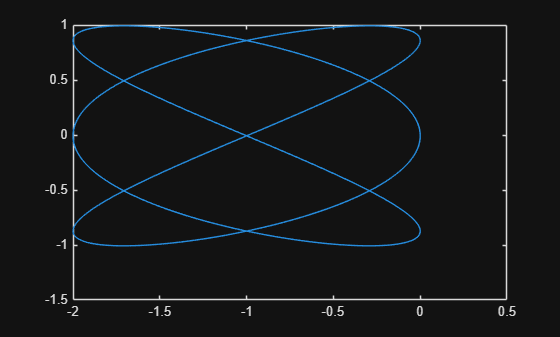

ux = ((X3 * a - a^3) / X1) * cos(a * t + delta) - ((X2 * a^2) / X1) * sin(a * t + delta);
uy = ((Y3 * b - b^3) / Y1) * cos(b * t) - ((Y2 * b^2) / Y1) * sin(b * t);
ul = 0.5 * (ux + uy);
ur = 0.5 * (ux - uy);


ss_x_direct = ss(Ax_direct, Bx_direct, [1,0,0], [0, 0]);
[x_state_direct, t, x_solve_direct] = lsim(ss_x_direct, [ul, ur], t);
ss_y_direct = ss(Ay_direct, By_direct, [1,0,0], [0, 0]);
[y_state_direct, t, y_solve_direct] = lsim(ss_y_direct, [ul, ur], t);

plot(x_state_direct, y_state_direct)